# Classification with Machine Learning and the TC Lab

Discover the power of supervised machine learning with the Classification Learner app, augmented with insights from the TCLab. Effortlessly train classification models from data exploration to model refinement, while also leveraging diverse classifiers for an intuitive learning experience. Unveil the latent potential within your datasets with the seamless integration of the TCLab. Purchase the TC Lab [https://](https://apmonitor.com/pdc/index.php/Main/PurchaseLabKit)[apmonitor.com/pdc/index.php/Main/PurchaseLabKit](https://apmonitor.com/pdc/index.php/Main/PurchaseLabKit)

First, With Campus-Wide License you have access to all MathWorks Toolboxes. If not, this module only requires the usage of the [**Statistics and Machine Learning Toolbox**](https://www.mathworks.com/products/statistics.html)**.**

Then, check out the [**Machine Learning Onramp**](https://www.mathworks.com/learn/tutorials/machine-learning-onramp.html) to learn about machine learning in MATLAB. Afterward, with this Live Script you can predict whether the TClab data shows that the TCLab is on, or off.

## 1.Summary

Classification with machine learning is through supervised (labeled outcomes), unsupervised (unlabeled outcomes), or with semi-supervised (some labeled outcomes) methods. From the many methods for classification the best one depends on the problem objectives, data characteristics, and data availability. Below is a complete compilation of the source code for supervised and unsupervised learning methods.

### TCLab data

Let's talk about generating labeled data using the TC Lab. You can control the heater input, switching it between 100% and 0% over several periods. This creates a dataset perfect for the Classification Learner. It's a simple yet effective way to gather the data you need for training your classification models. Generate labeled data where the [**TCLab heater**](https://apmonitor.com/heat.htm)  input is either on at 100% or at 0% for multiple periods for a total of *500 s*. 

## **2. Generate a Small Data Set**

We test the classifier by splitting the data set into a training and test set. The data is generated from a TCLab or accessed at the link below.

[**Data for Testing**](https://apmonitor.com/do/uploads/Main/tclab_data5.txt)

a. Load data from a server apmonitor (this is the option if you do not have the TCLab)

isTcLab=false;
if isTcLab
    test = readtable('https://apmonitor.com/do/uploads/Main/tclab_data5.txt');
    Data = load('machine_learning_data.mat');
end

b. Used the collected from the TCLab - *Small Data Set (500 s). *The [video ](https://www.youtube.com/watch?v=IvxGXYAHb4I)shows the process of callecting data with the TCLab. The heater Q1 input is either on at 100% or at 0% for multiple periods.

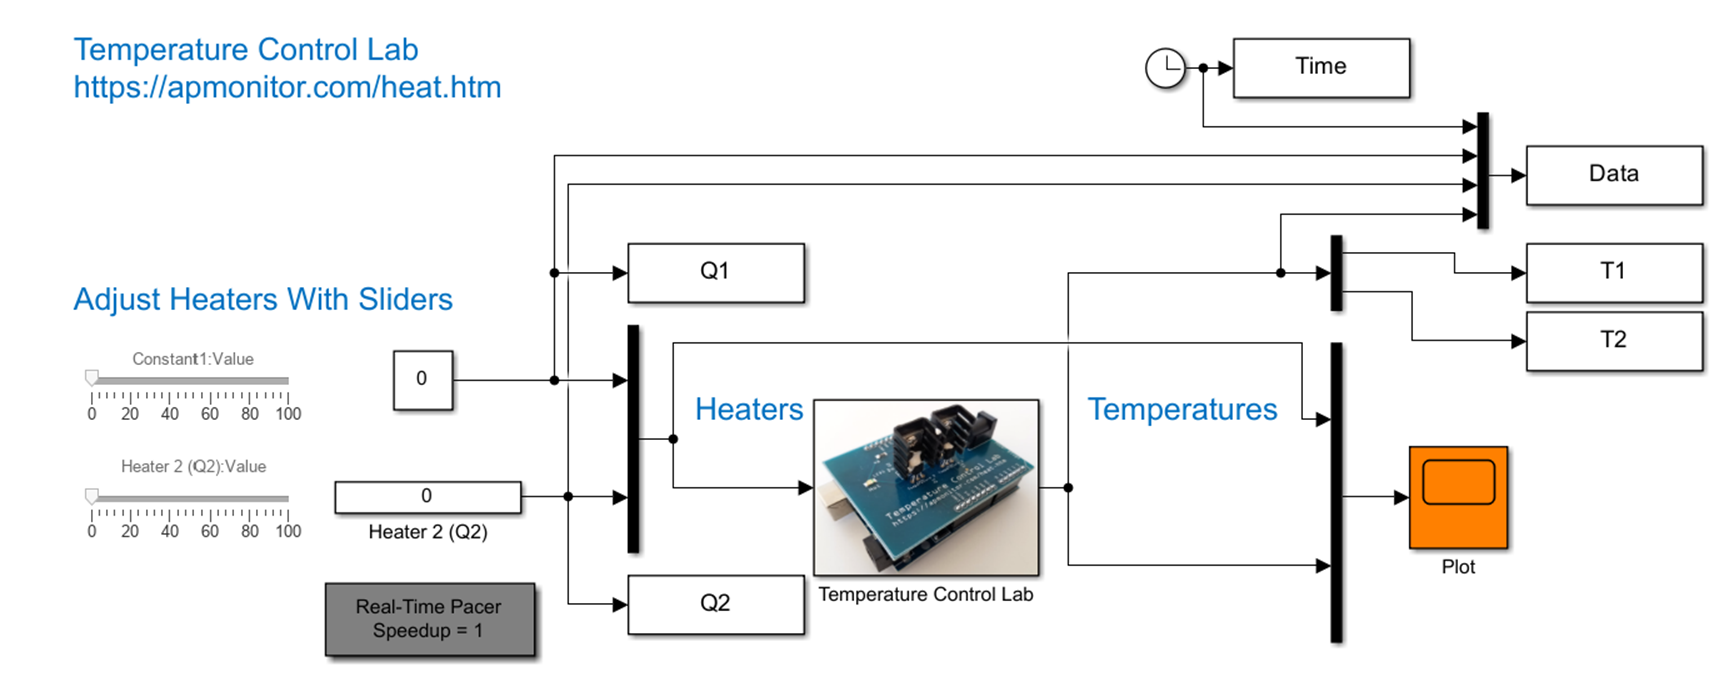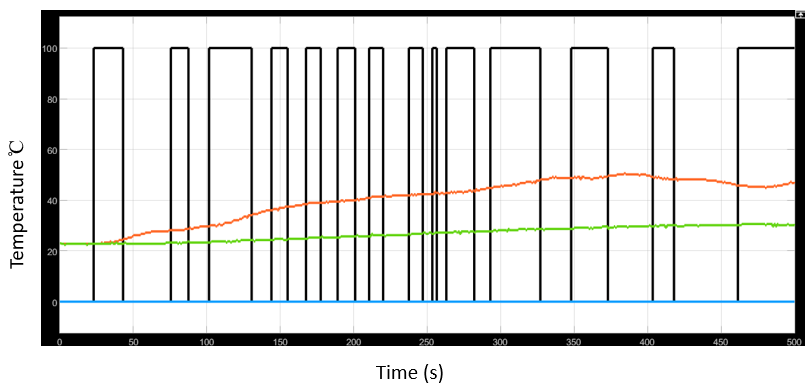

This is the collected data. 

load('Data1.mat'); %loading the data that has been collected previously
Time = Data(:,1);
Q1 = Data(:,2);
Q2 = Data(:,3);
T1 = Data(:,4);
T2 = Data(:,5);
test = table(Time,Q1,Q2,T1,T2)

test = 1001×5 table
    Time    Q1     Q2      T1        T2  
    ____    ___    __    ______    ______

      0       0    0         23        23
    0.5       0    0         23        23
      1       0    0      24.78    24.291
    1.5     100    0      24.78    24.291
      2     100    0      24.78    24.291
    2.5     100    0      24.78    24.291
      3     100    0     25.269    24.291
    3.5     100    0     25.269    24.291
      4     100    0      24.78     24.78
    4.5     100    0      24.78     24.78
      5     100    0     25.269    24.291
    5.5     100    0     25.269    24.291
      6     100    0     24.291    24.291
    6.5     100    0     24.291    24.291
      7     100    0      24.78     24.78
    7.5     100    0      24.78     24.78


### Processing the callected data

Add Derivative feature

test.dT1dt = zeros(length(test.Time),1);
test.d2T1dt2 = zeros(length(test.Time),1);
for i = 2:length(test.Time)
    dt = test.Time(i) - test.Time(i-1); 
    test.dT1dt(i) = (test.T1(i) - test.T1(i-1))/dt;
    test.d2T1dt2(i) = (test.dT1dt(i) - test.dT1dt(i-1))/dt;
end

Rescale to between 0 and 1

test = normalize(test,'range')

test = 1001×7 table
    Time     Q1    Q2       T1         T2         dT1dt       d2T1dt2  
    _____    __    __    ________    _______    _________    __________

        0    0     0            0          0      0.35448           0.5
    0.001    0     0            0          0      0.35448           0.5
    0.002    0     0     0.065454    0.18044            1             1
    0.003    1     0     0.065454    0.18044      0.35448    5.5511e-17
    0.004    1     0     0.065454    0.18044      0.35448           0.5
    0.005    1     0     0.065454    0.18044      0.35448           0.5
    0.006    1     0     0.083426    0.18044      0.53173       0.63729
    0.007    1     0     0.083426    0.18044      0.35448       0.36271
    0.008    1     0 

## **3. Loading Large Data**

train = readtable('https://apmonitor.com/do/uploads/Main/tclab_data6.txt')

train = 3601×5 table
    Time    Q1    Q2     T1       T2  
    ____    __    __    _____    _____

      0     0     0     16.06       16
      1     0     0     16.06    15.97
      2     0     0     16.06    16.03
      3     0     0     16.03       16
      4     0     0     16.03    15.94
      5     0     0     16.06       16
      6     0     0     16.03       16
      7     0     0     16.06    15.94
      8     0     0     16.06    15.97
      9     0     0     16.06    15.97
     10     0     0     16.06    15.94
     11     0     0     16.06    15.97
     12     0     0     16.06    15.97
     13     0     0     16.06    15.94
     14     0     0     16.06    15.94
     15     0     0     16.06    15.94


### Processing the loaded data

Add Derivative feature

train.dT1dt = zeros(length(train.Time),1);
train.d2T1dt2 = zeros(length(train.Time),1);
for i = 2:length(train.Time)
    dt = train.Time(i) - train.Time(i-1); 
    train.dT1dt(i) = (train.T1(i) - train.T1(i-1))/dt;
    train.d2T1dt2(i) = (train.dT1dt(i) - train.dT1dt(i-1))/dt;
end

Rescale to between 0 and 1

train = normalize(train,'range')

train = 3601×7 table
       Time       Q1    Q2        T1           T2         dT1dt     d2T1dt2
    __________    __    __    __________    _________    _______    _______

             0    0     0     0.00068244    0.0089686        0.5    0.33333
    0.00027778    0     0     0.00068244     0.006278        0.5    0.33333
    0.00055556    0     0     0.00068244     0.011659        0.5    0.33333
    0.00083333    0     0              0    0.0089686    0.49107    0.32738
     0.0011111    0     0              0    0.0035874        0.5    0.33929
     0.0013889    0     0     0.00068244    0.0089686    0.50893    0.33929
     0.0016667    0     0              0    0.0089686    0.49107    0.32143
     0.0019444    0     0     0.00068244    0.0035874   

Select and scale (0-1) the features of the data such as temperature, and temperature derivatives. Use the measured temperature and derivatives and heater value labels to create a classifier that predicts when the heater is on or off. Validate the classifier with new data that was not used for training.

## **4. Classification Learner**

- Run the below code to open the classification Learner

- Select New Session from Workspace 

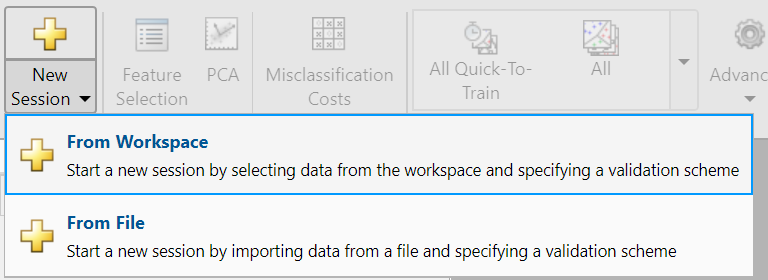

        3. Select the train data set, Q1 as the response variable, and the other features as predictors which will be used to predict whether the heater is on.

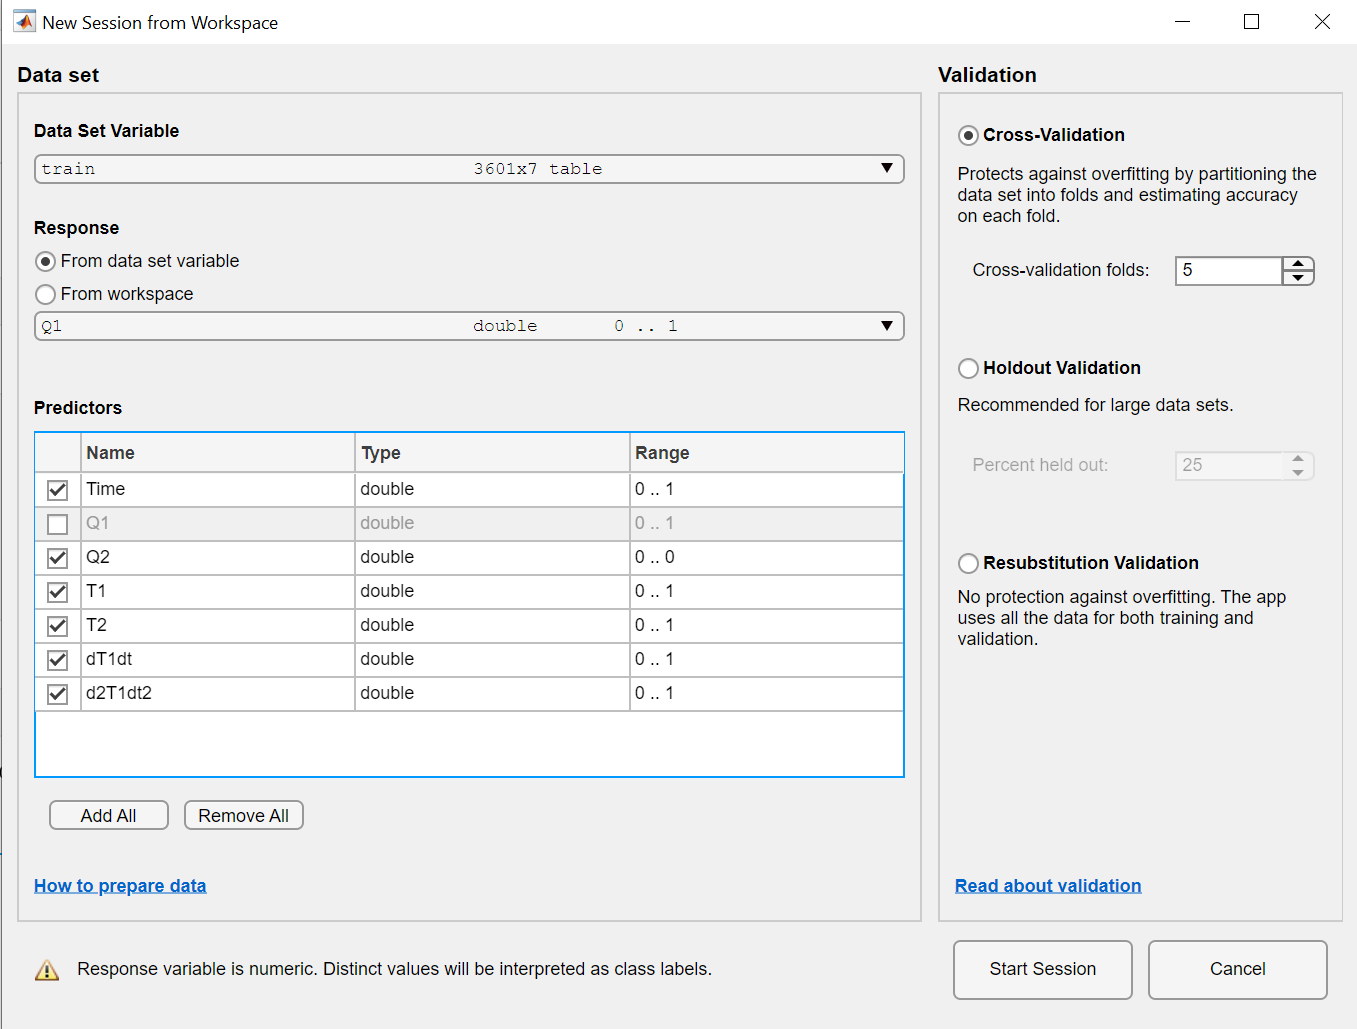

        4. Click Start Session

        5. Within the Classification Learner app, select  All Quick-To-Train in the model type menu

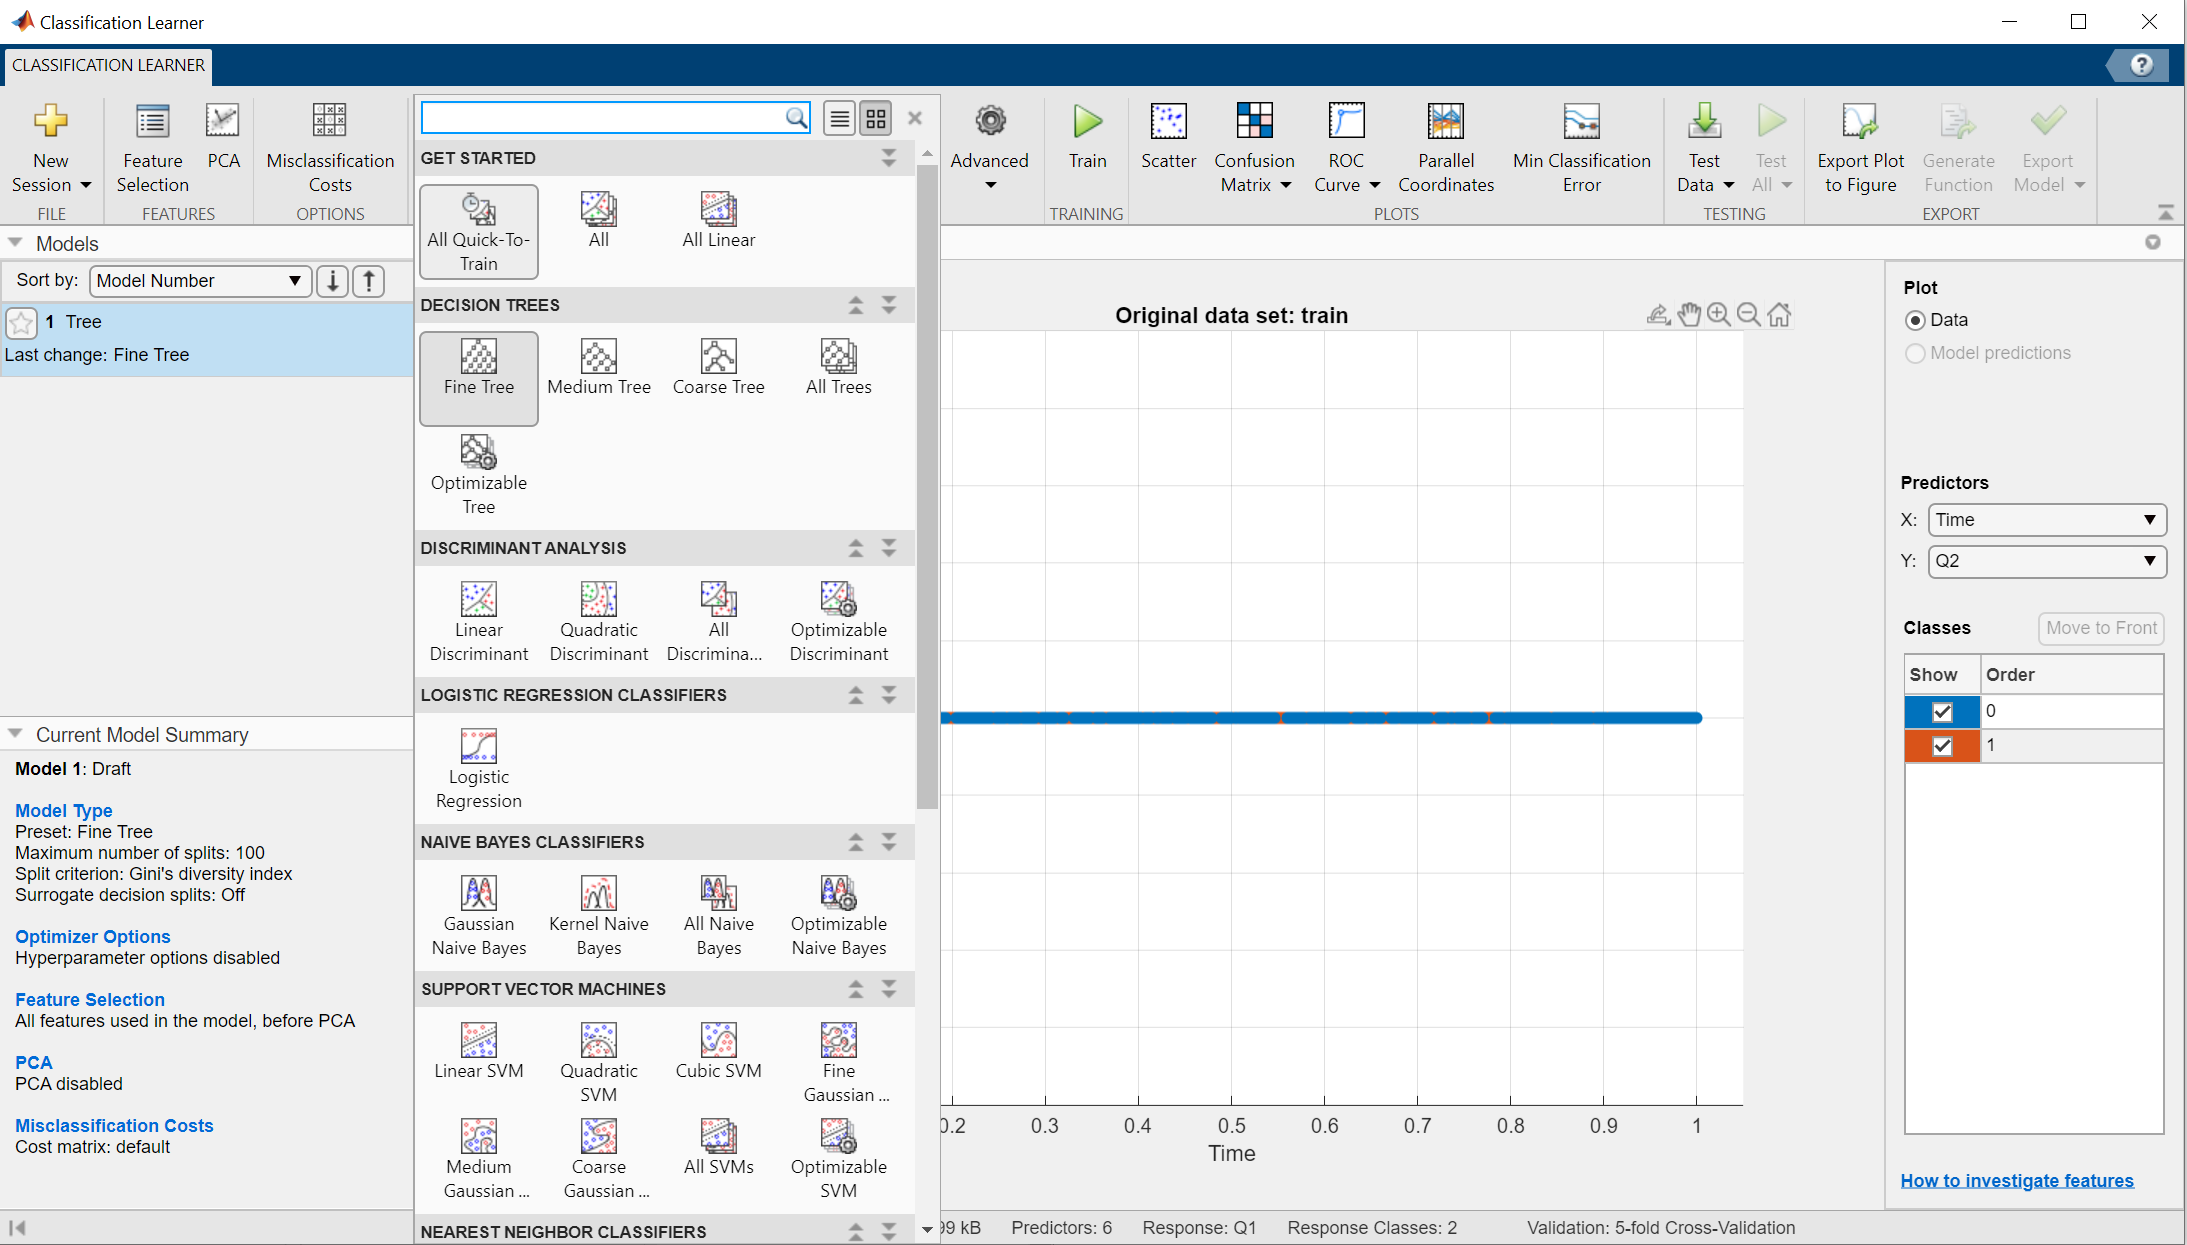

        6. Train the models and compare the accuracies and trends of different models using the provided graph

### Use the Classification Learner

classificationLearner

It is a work by